# Try4 version1 （长方形，高斯迭代，for循环，相容误差）

尝试for循环，用相容误差代替迭代误差

## Paramètre


x=10;   %longueur en x
y=5;   %longueur en y
h=.1;  %pas
m=0:h:x;
n=0:h:y;
T=zeros(length(n),length(m))

T =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

length(T)

ans = 101

## Condition frontière

T(1,:)=10;
T(:,1)=10;
T(length(n),:)=5;
T(:,length(m))=1;
T1=T

T1 =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

[xq,yq] = meshgrid(m, n)

xq =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    

yq =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    

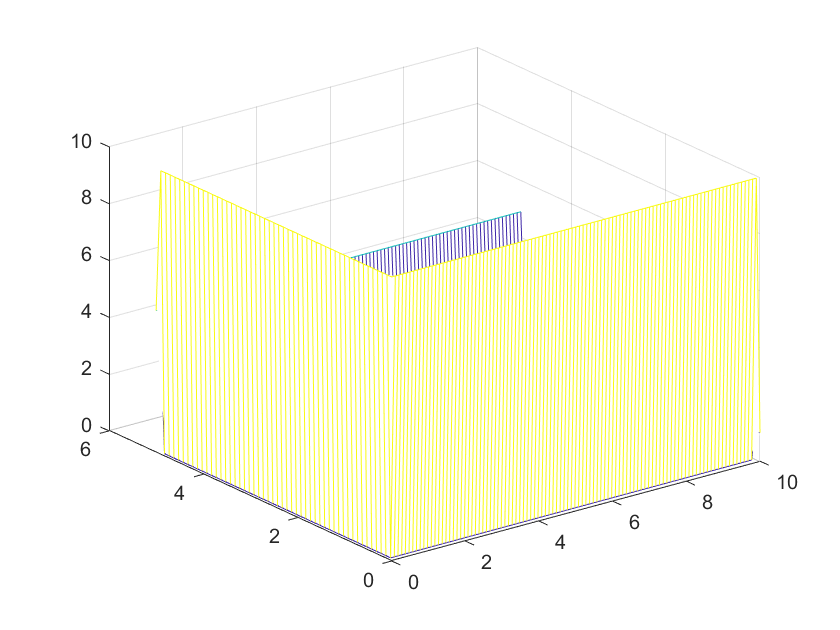

mesh(xq,yq,T)

% M=moviein(length(n)-2);

## i dislike for

accuracy=.00000001; count=0;
flag=zeros(length(n),length(m));
% error=zeros(length(n),length(m));
num=(length(n)-2)*(length(m)-2);
while count<=num
    for i=2:length(n)-1     %indice ligne
        for j=2:length(m)-1 %indice colonne
            if flag(i,j)==0
                temp_float=T(i,j);
                % -----N S W E -------%
                T(i,j)=(T(i-1,j) ...    %North
                +T(i+1,j) ...       %South
                +T(i,j-1) ...       %West
                +T(i,j+1))/4 ...    %East
                -(h^2*.2)/4  ;       %complément si laplacien non nul  
                % -----/ N S W E -------%
                cur_err=(T(i,j)-temp_float)/T(i,j);
                %T=T1;
                
%                 M(i,j)=getframe(gcf);
            end
            if abs(cur_err)<=accuracy
                %error(i,j)=cur_err;
                 flag(i,j)=1;
                count=count+1;
            end
        end
    end    
end
count

count = 4871

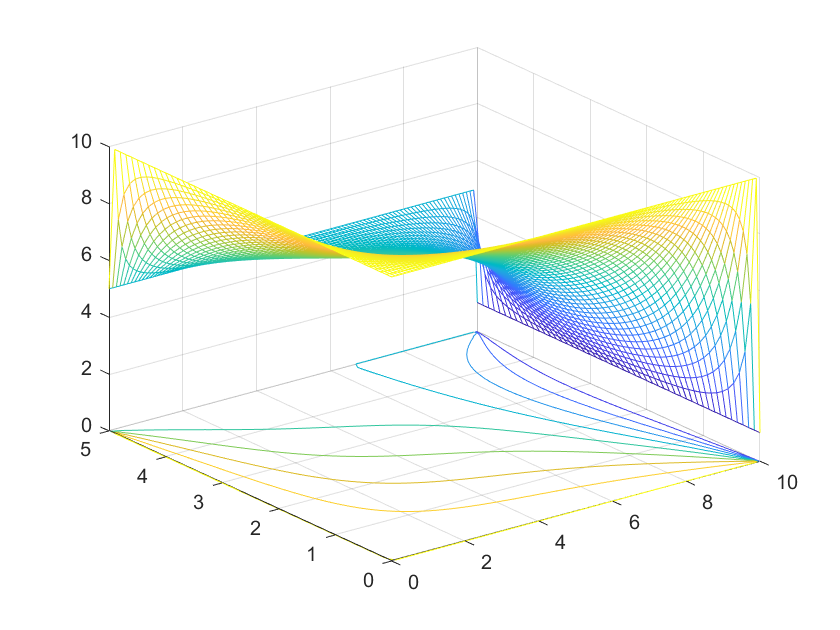

% movie(M)

% while max(max(e))>=0.1
%     for i=2:length(n)-1     %indice ligne
%         for j=2:length(m)-1 %indice colonne
%             T(i,j)=(T(i-1,j) ...    %North
%                 +T(i+1,j) ...       %South
%                 +T(i,j-1) ...       %West
%                 +T(i,j+1))/4 ...    %East
%                 -(h^2*.2)/4  ;       %complément si laplacien non nul
%             count=count--1;
%             e=(T-temp)/T;
%         end
%     end
% end

meshc(xq,yq,T)

下列代码长时间运行后也没有结果

e=1; count=0;

while max(max(e))>=0.1

    for i=2:length(n)-1     %indice ligne

        for j=2:length(m)-1 %indice colonne

            T(i,j)=(T(i-1,j) ...    %North

                +T(i+1,j) ...       %South

                +T(i,j-1) ...       %West

                +T(i,j+1))/4 ...    %East

                -(h^2*.2)/4  ;       %complément si laplacien non nul

            count=count--1;

            e=(T-temp)/T;

        end

    end

end

在使用相容误差的代码中，第一版本一直在运行无法得出结果，原因：

变量名不一致，我用了temp和temp_float

## boucle for version 2

accuracy=.1; count=0;

flag=zeros(length(n),length(m));

% error=zeros(length(n),length(m));

num=(length(n)-2)*(length(m)-2);

while count<num

    for i=2:length(n)-1     %indice ligne

        for j=2:length(m)-1 %indice colonne

            if flag(i,j)==0

                temp_float=T(i,j);

                % -----N S W E -------%

                T(i,j)=(T(i-1,j) ...    %North

                +T(i+1,j) ...       %South

                +T(i,j-1) ...       %West

                +T(i,j+1))/4 ...    %East

                -(h^2*.2)/4  ;       %complément si laplacien non nul  

                % -----/ N S W E -------%

                cur_err=(T(i,j)-temp_float)/T(i,j);

            end

            if abs(cur_err)<=accuracy

                %error(i,j)=cur_err;

                flag(i,j)=1;

                count=count+1;

            end

        end

    end    

end